clear;
addpath('./lib');
altitude_waypoints = [  0,  0;
                        10, 50;
                        50, 50;
                        60, 0   ];
throttle_models = getThrottleModels();
m_inert = 250*0.453592; %<----- If this is wrong, crucify nicholas bonnett

[mass_data, history] = optimizeMass(altitude_waypoints, throttle_models, m_inert, 0.2);

close all;
fprintf("Gross Takeoff Mass: %.4f kg, %.4f lbs\n", mass_data(1), mass_data(1)/0.453592);

Gross Takeoff Mass: 171.0234 kg, 377.0423 lbs


fprintf("Initial Propellant Mass: %.4f kg, %.4f lbs\n", mass_data(2), mass_data(2)/0.453592);

Initial Propellant Mass: 38.4167 kg, 84.6944 lbs


fprintf("Tank Mass: %.4f kg, %.4f lbs\n", mass_data(3), mass_data(3)/0.453592);

Tank Mass: 19.2085 kg, 42.3474 lbs


fprintf("Final Mass: %.4f kg, %.4f lbs\n", mass_data(4), mass_data(4)/0.453592);

Final Mass: 165.7588 kg, 365.4359 lbs


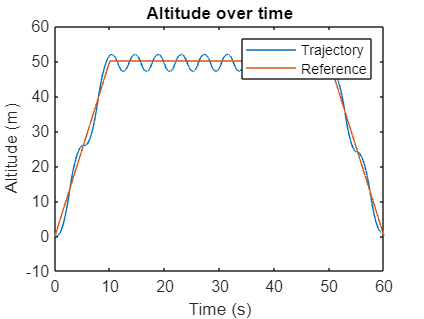


figure;
plot(history(:, 1), history(:, 2));
hold on;
plot(history(:, 1), history(:, 5));
legend("Trajectory", "Reference");
title("Altitude over time");
xlabel("Time (s)");
ylabel("Altitude (m)");